# Testing del metodo di Jacobi

Si testa il software su matrici sparse di notevoli dimensioni, generate usando funzioni Matlab non singolari e ben condizionate. Si illustra, attraverso grafico, la struttura delle matrici di test.

caso in cui il raggio spettrale < 1 e buon condizionamento

% CONVERGE

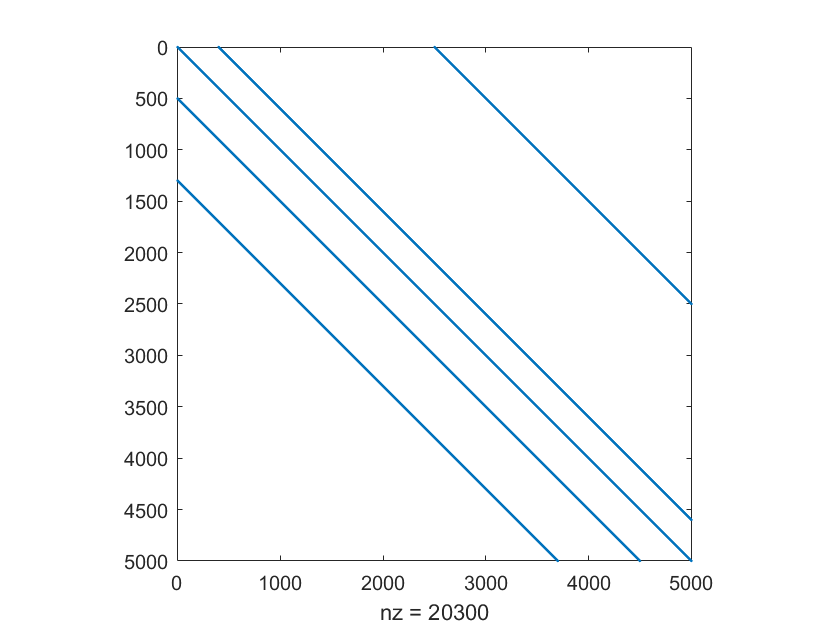

n = 5000;
e = ones(n,1);
Z = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
spy(Z)

b = Z*e;
c = condest(Z)

c = 2.2693

[sol, niter] = Jacobi(Z, b);

    0.4000

    0.3306



niter

niter = 11

err = norm(e-sol)/norm(sol)

err = 2.9691e-08

res = norm(b-Z*sol)/norm(b)

res = 2.2844e-08

Test matrice di Toeppen (ben condizionata).

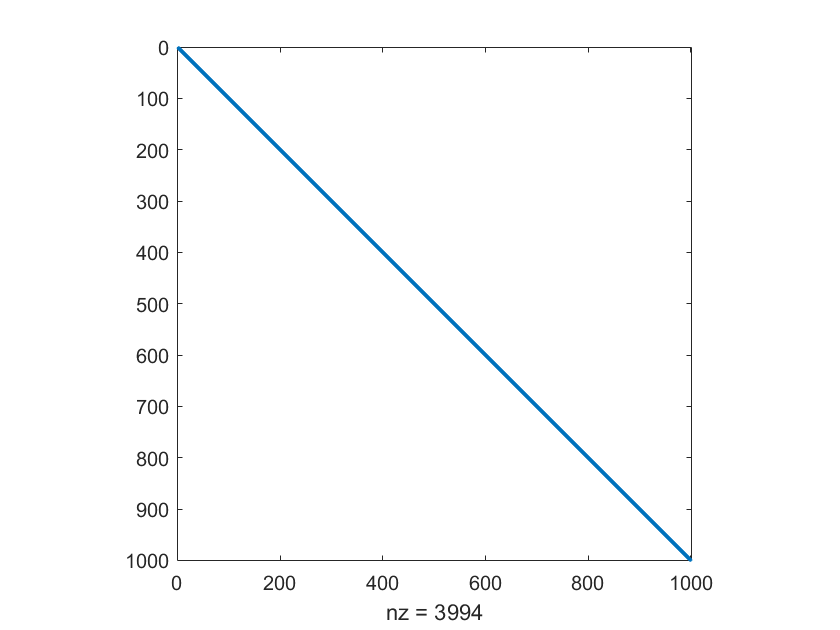

T = gallery('toeppen',1000);
spy(T)

b = T*ones(1000,1);
[sol6, niter6] = Jacobi(T,b);

Error using Jacobi (line 23)
La matrice A ha elementi nulli sulla diagonale. Riordinare la matrice e rieseguire l'algoritmo.

niter6
sol6

Altro test: aumentiamo richiesta di cifre corrette

[sol2, niter2] = Jacobi(Z, b, 10^-12);
niter2

niter2 = 22

err2 = norm(e-sol2)/norm(sol2)

err2 = 9.0076e-14

res2 = norm(b-Z*sol2)/norm(b)

res2 = 5.4159e-14

caso in cui il raggio spettrale < 1 (ma maggiore di prima) e buon condizionamento (ma maggiore rispetto a prima)

% CONVERGE ma con più iterazioni

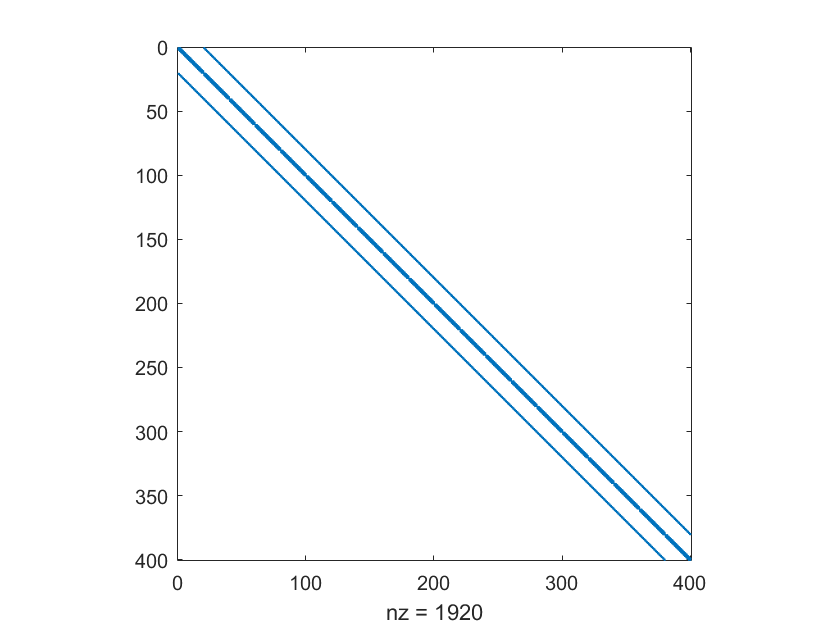

X = gallery('poisson',20);
spy(X)

size(X)

ans =    400   400


condest(X)

ans = 258.4520

x = ones(400,1);
b = X*x;
[sol3, niter3] = Jacobi(X,b,10^-6,1000);

     1

    0.9888



niter3

niter3 = 873

err3 = norm(x-sol3)/norm(sol3)

err3 = 4.6238e-05

caso in cui diagonale non strettamente dominante e buon condizionamento

% (vale per tutti i tol)

% NON CONVERGE anche con Tol = 10^-15 e aumentando le iterazioni.

W = spdiags([e 5*e 2*e -e e], [-1300 -500 0 400 2500], n, n);
spy(W);

b = W*e;
[sol4, niter4] = Jacobi(W,b,10^(-15));

     4

    3.3204



niter4

niter4 = 500

condizionamento = 150.4169, norma di B = 1, p(B) =  0.9808 (TOL : -12 to -15)

% CONVERGE dopo 1613

Matrice malcondizionata, raggio spettrale pari a 1.

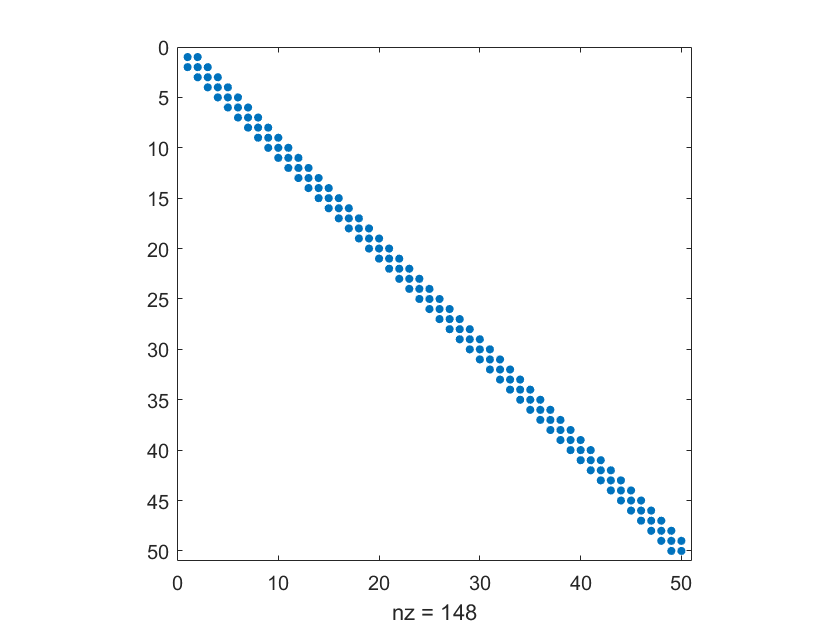

D = gallery('dorr',50);
spy(D)

b = D*ones(50,1);
[sol5, niter5] = Jacobi(D,b,10^-6,30000);

Norma:
     1

Raggio spettrale:
    1.0000



niter5

niter5 = 30000

sol5

sol5 =     0.5689
    0.3470
    0.2304
    0.1679
    0.1336
    0.1145
    0.1036
    0.0972
    0.0934
    0.0910
